
a = 1 + mod(109,3);

Problem 1

Fs = 100

Fs = 100

t = 0:1/Fs:10;
F = (5+5*a-2-2*a)*t/10 + 2+2*a ;
y = sin(2*pi*F.*t);

SubProblem 1

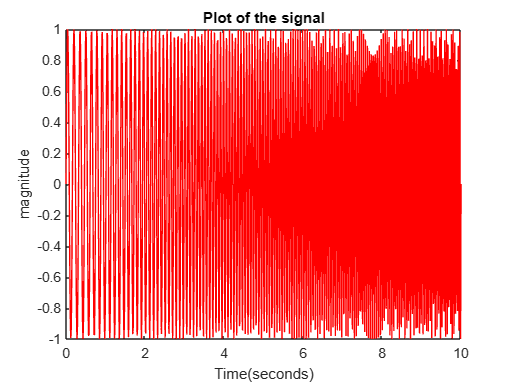

plot(t,y,"r")
title("Plot of the signal")
xlabel("Time(seconds)")
ylabel("magnitude")

SubProblem2

Fs =100

Fs = 100

f = 0:Fs/(length(y)-1):Fs;
Y = fft(y);
hold on
plot(f,abs(Y)/(length(y)-1),"b")
[value , idx] = findpeaks(abs(Y)/(length(y)-1));
f(idx) %frequency components

ans =     7.2000    8.2000    8.9000    9.5000   10.0000   10.4000   10.8000   11.1000   11.5000   11.8000   12.1000   12.4000   12.7000   12.9000   13.2000   13.4000   13.7000   13.9000   14.1000   14.3000   14.6000   14.8000   15.0000   15.2000   15.4000   15.7000   15.9000   16.1000   16.3000   16.6000   16.8000   17.1000   17.3000   17.6000   17.9000   18.2000   18.5000   18.9000   19.2000   19.6000   20.0000   20.5000   21.1000   21.8000   22.9000   77.2000   78.3000   79.0000   79.6000   80.1000


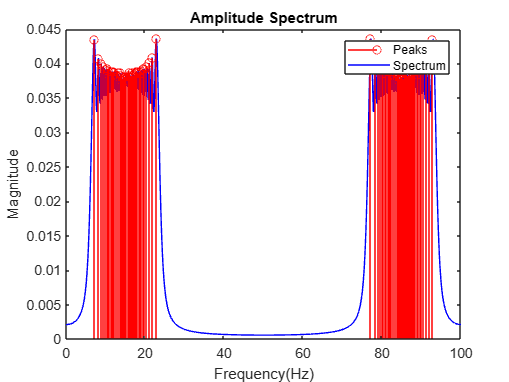

stem(f(idx),value,"r")
title("Amplitude Spectrum")
xlabel("Frequency(Hz)")
ylabel("Magnitude")
legend("Peaks","Spectrum")
hold off

SubProblem 3

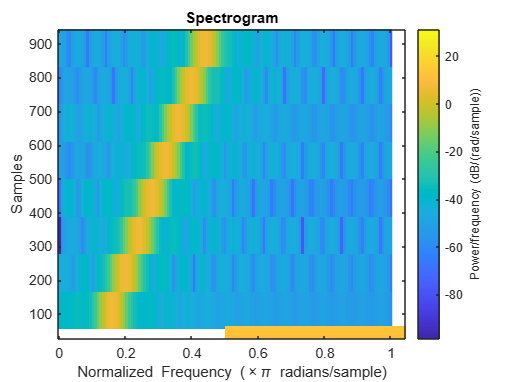

spectrogram(y),imagesc()
title("Spectrogram")

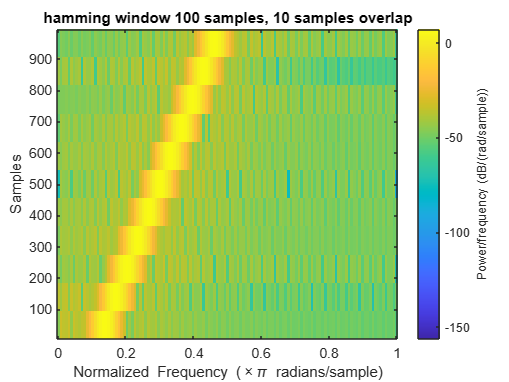

spectrogram(y,hamming(100),10)
title("hamming window 100 samples, 10 samples overlap")

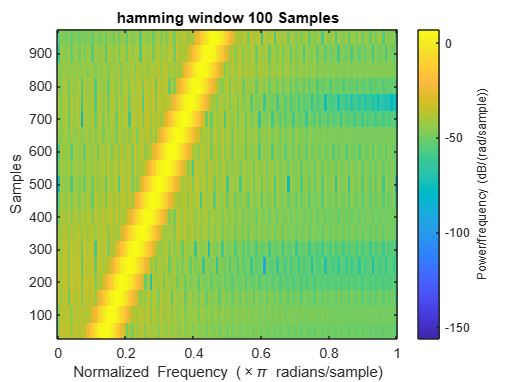

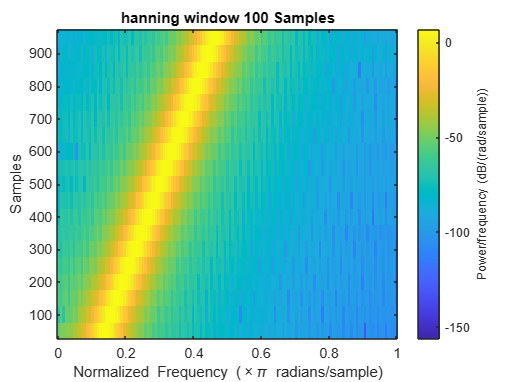

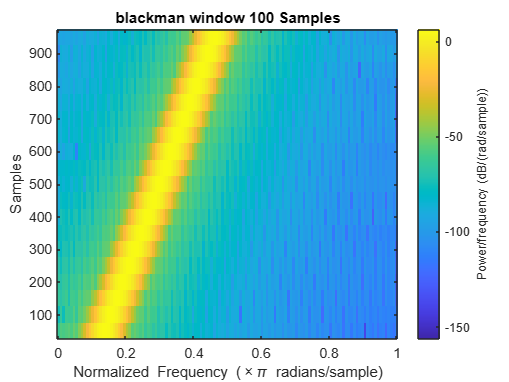

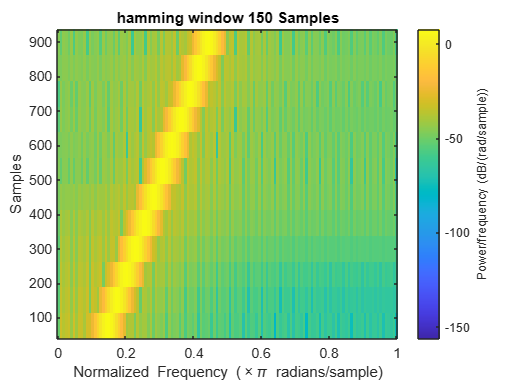

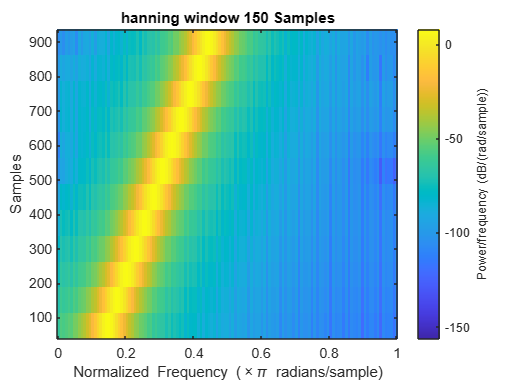

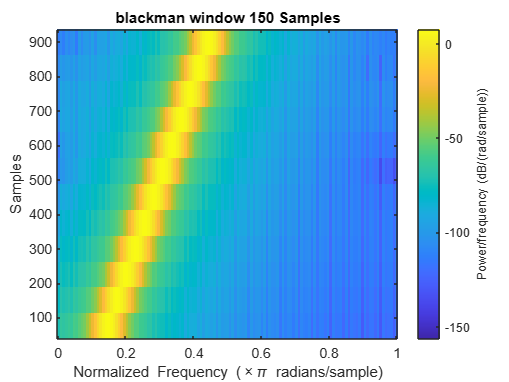

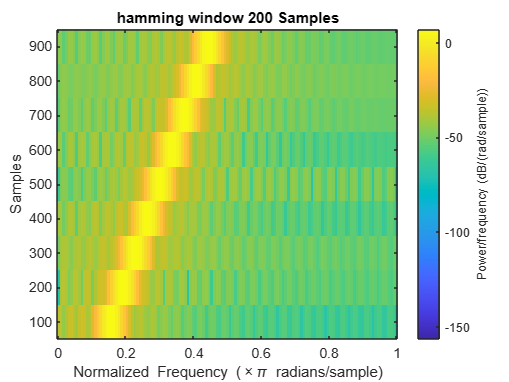

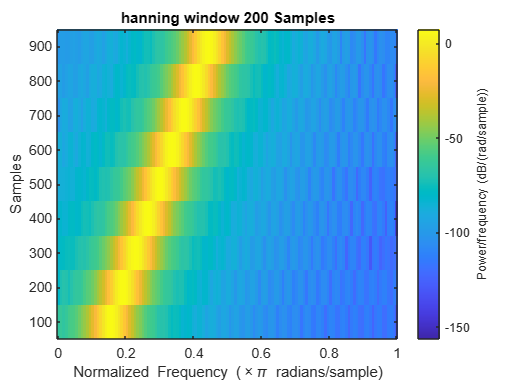

for i = 100:50:200
    figure;
    spectrogram(y,hamming(i))
    title("hamming window " + i + " Samples")
    figure;
    spectrogram(y,hann(i))
    title("hanning window " + i + " Samples")
    figure;
    spectrogram(y,blackman(i))
    title("blackman window " + i + " Samples")
end

Problem 2

SubProblem 1

file = "instru"+a+".wav"

file = "instru2.wav"

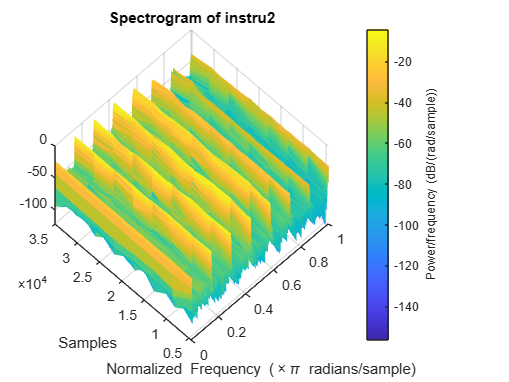

[s, Fs] = audioread(file);
figure;
spectrogram(s),view(-45,65)
title("Spectrogram of instru2")

f = 0:Fs/(length(s)-1):Fs

f = 1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0014


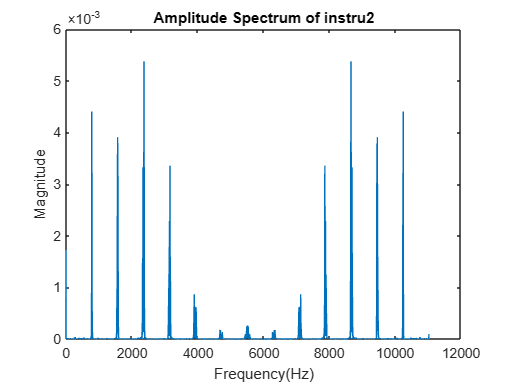

Y = fft(s);
figure;
plot(f,abs(Y)/(length(s)))
title("Amplitude Spectrum of instru2")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

[value idx] = max(abs(Y)/(length(s)));
fund_freq = f(idx)

fund_freq = 2.3692e+03

SubProblem 2

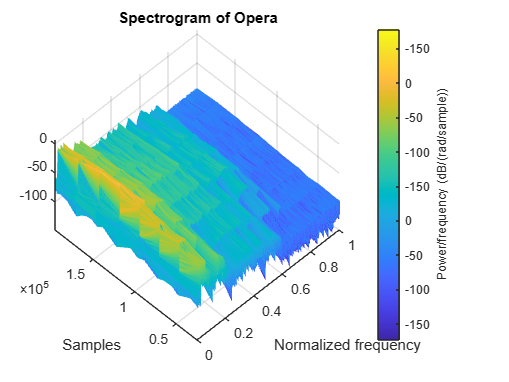

[s1,Fs1] = audioread("Opera.wav");
spectrogram(s1),view(-45,60),imagesc()
title("Spectrogram of Opera")
ylabel("Samples")
xlabel("Normalized frequency")

Problem  3

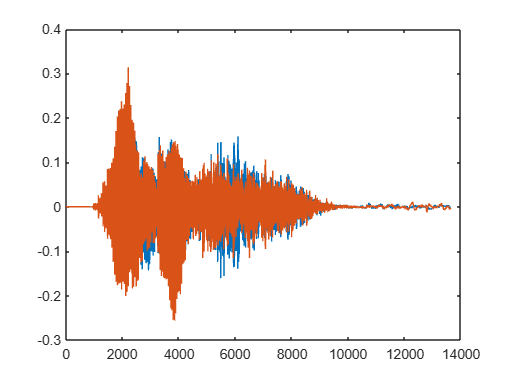

[h, Fs2] = audioread("my name.wav");
plot(h)

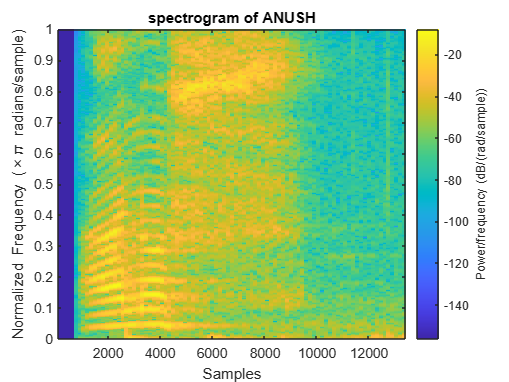

spectrogram(h(:,2),hamming(300),150,4000,'yaxis')
title("spectrogram of ANUSH")